count = 1

number = 1

model = 'iPhone16,2'

rep = 800

bins = 1000

data = 1×4 table
    싱글 평균    싱글 중간값    멀티 평균    멀티 중간값
    ________    __________    ________    __________

     2877.6        2930        7162.8        7285   


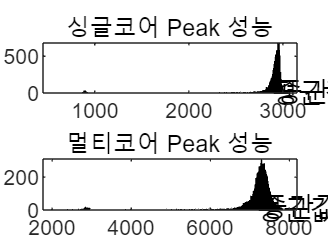

yesorno = 'n'

yesorno = 'default';
count = 0;
while yesorno == "default" || yesorno == "y" || yesorno == "yes" || yesorno == "ok"
% HTML을 파싱한 결과 점수 데이터가 시작하는 부분과 끝나는 부분을 찾았다.

count = count + 1


% 모델 여러개 한꺼번에 입력하는것
% 이거 참고할것
% https://endowkim.tistory.com/entry/eval%EB%A1%9C-%EC%88%9C%EC%B0%A8%EC%A0%81%EC%9D%B8-%EB%B3%80%EC%88%98%EB%A5%BC-%EB%A7%8C%EB%93%A4%EC%96%B4-%EB%B3%B4%EC%9E%90

number = input('찾아볼 모델 종류의 수를 숫자로 입력하세요 = ')

for i=1:number

    


model = input('모델명을 입력하세요 .. = ', 's') %스트링 입력

pivot1 = sprintf("Single-Core Score\n</span>\n<span class='list-col-text-score'>");
pivot2 = sprintf("Multi-Core Score\n</span>\n<span class='list-col-text-score'>");
last = sprintf("</span>");

temp = str2double(extractBetween(webread(sprintf('https://browser.geekbench.com/search?page=1&q=%s', model)), pivot1, last));

while isempty(temp) == 1
    model = input('다른 모델명을 입력하세요 .. = ', 's')
    temp = str2double(extractBetween(webread(sprintf('https://browser.geekbench.com/search?page=1&q=%s', model)), pivot1, last));
end

rep = input('몇 페이지를 가져올까요? 한 페이지 당 25개의 결과가 있습니다. = ')

single = [];
multi = [];

bins = input('히스토그램의 구간을 몇 개로 나눌까요? = ')

for i = 1:rep
    page = sprintf('https://browser.geekbench.com/search?page=%d&q=%s', i, model);
    base = webread(page);
    temp1 = str2double(extractBetween(base, pivot1, last));
    single = [single; temp1];
    temp2 = str2double(extractBetween(base, pivot2, last));
    multi = [multi; temp2];
end




if yesorno == 'default'
    
    data = table(mean(single), median(single), mean(multi), median(multi));
    data.Properties.VariableNames = ["싱글 평균", "싱글 중간값", "멀티 평균", "멀티 중간값"]
    
    
    clf
    
    hold off
    subplot(2,1,1)
    histogram(single, bins)
    title("싱글코어 Peak 성능")
    text(mean(single), 0, sprintf("평균값: %.1f", mean(single)))
    text(median(single), 20, sprintf("중간값: %.1f", median(single)))
    
    
    subplot(2,1,2)
    histogram(multi, bins)
    title("멀티코어 Peak 성능")    
    text(mean(multi), 0, sprintf("평균값: %.1f", mean(multi)))
    text(median(multi), 20, sprintf("중간값: %.1f", median(multi)))
    
    
else
    data(count, :) = {mean(single), median(single), mean(multi), median(multi)}
    yesorno = input('그래프를 겹쳐 그릴까요? y/yes/ok 중 하나를 입력하면 겹쳐 그립니다. = ', 's')
    if yesorno == "y" || yesorno == "yes" || yesorno == "ok"
    

    
    subplot(2,1,1)
    hold on
    histogram(single, bins)
    title("싱글코어 Peak 성능")
    text(mean(single), (count-1)*5, sprintf("%d의 평균값: %.1f", count, mean(single)))
    text(median(single), 20+(count-1)*5, sprintf("%d의 중간값: %.1f", count, median(single)))
    
    subplot(2,1,2)
    hold on
    histogram(multi, bins)
    title("멀티코어 Peak 성능")
    text(mean(multi), (count-1)*5, sprintf("%d의 평균값: %.1f", count, mean(multi)))
    text(median(multi), 20+(count-1)*5, sprintf("%d의 중간값: %.1f", count, median(multi)))
    
    else
    
    clf
    hold off
    subplot(2,1,1)
    histogram(single, bins)
    title("싱글코어 Peak 성능")
    text(mean(single), 0, sprintf("%d의 평균값: %.1f", count, mean(single)))
    text(median(single), 20, sprintf("%d의 중간값: %.1f", count, median(single)))
    
    hold off
    subplot(2,1,2)
    histogram(multi, bins)
    title("멀티코어 Peak 성능")    
    text(mean(multi), 0, sprintf("%d의 평균값: %.1f", count, mean(multi)))
    text(median(multi), 20, sprintf("%d의 중간값: %.1f", count, median(multi)))
    
    end
end





yesorno = input('다른 정보를 원하면, y/yes/ok 중 하나를 입력하십시오 = ', 's')
end
end